## Project SPBD 2022

## Music Note Extraction

## Turn a song into playable sheet music

Leonardo Lavagna

## Part I . Set up

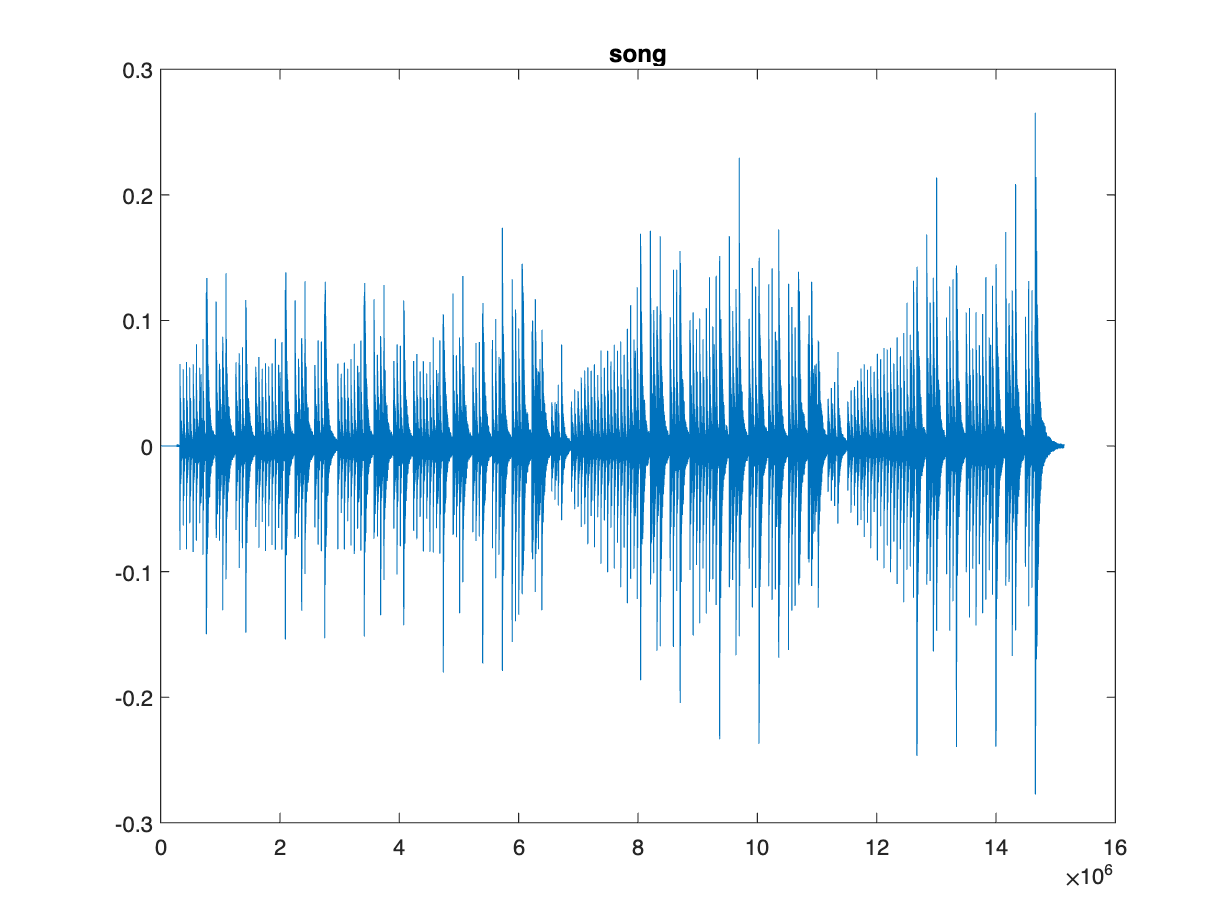

clear; clc; clf; close all
% set this to false to hear audio throughout program
mute = false;

[song,Fs] = audioread('perelisa.mp3');
% speed up song (if needed)
Fs = Fs*4;
figure, plot(song(:,1)), title('song')

parameters (each song has its own) needed for the window selection below

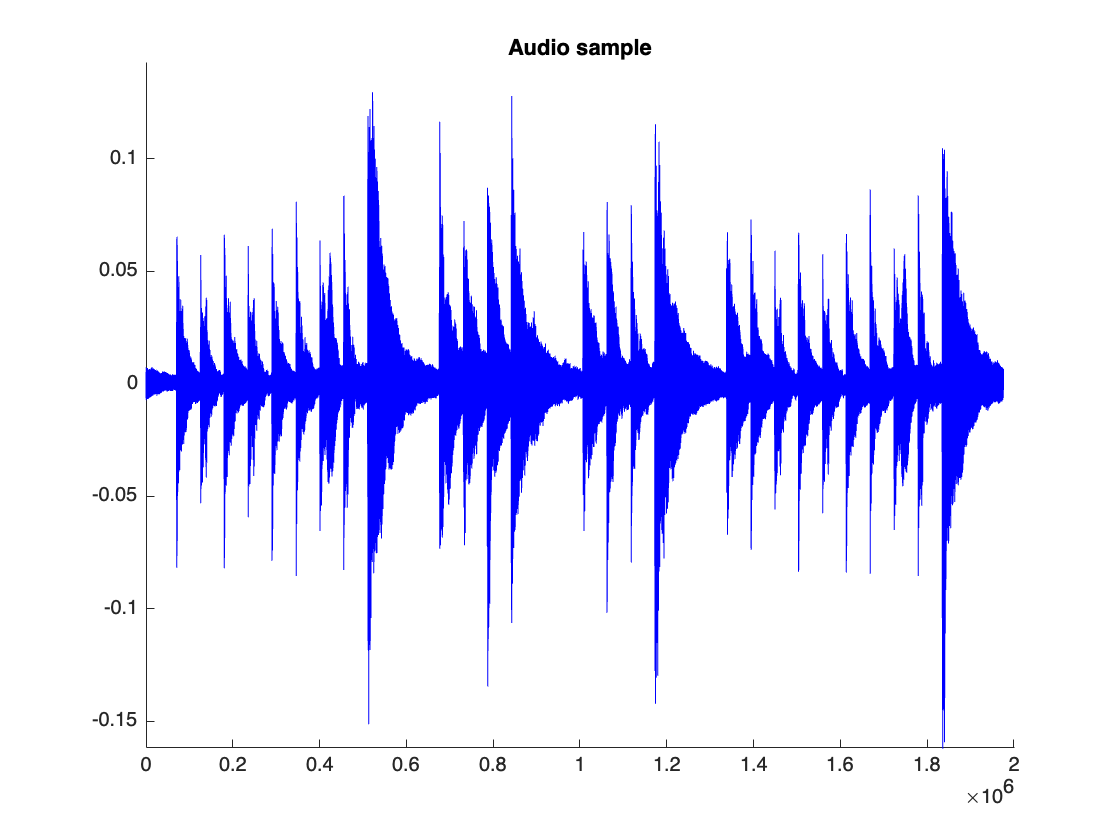

t1 = 2.9e6; t2 = 4.9e6;

% select a window of the song
y = song(t1:t2);
[~,n] = size(y);
t = linspace(t1,t2,n);
if ~mute, plotsound(y,Fs,mute); end

audiowrite('song_window.wav',y,Fs);

## Part II . Processing

downsample by m here m depends on the song chosen and the window

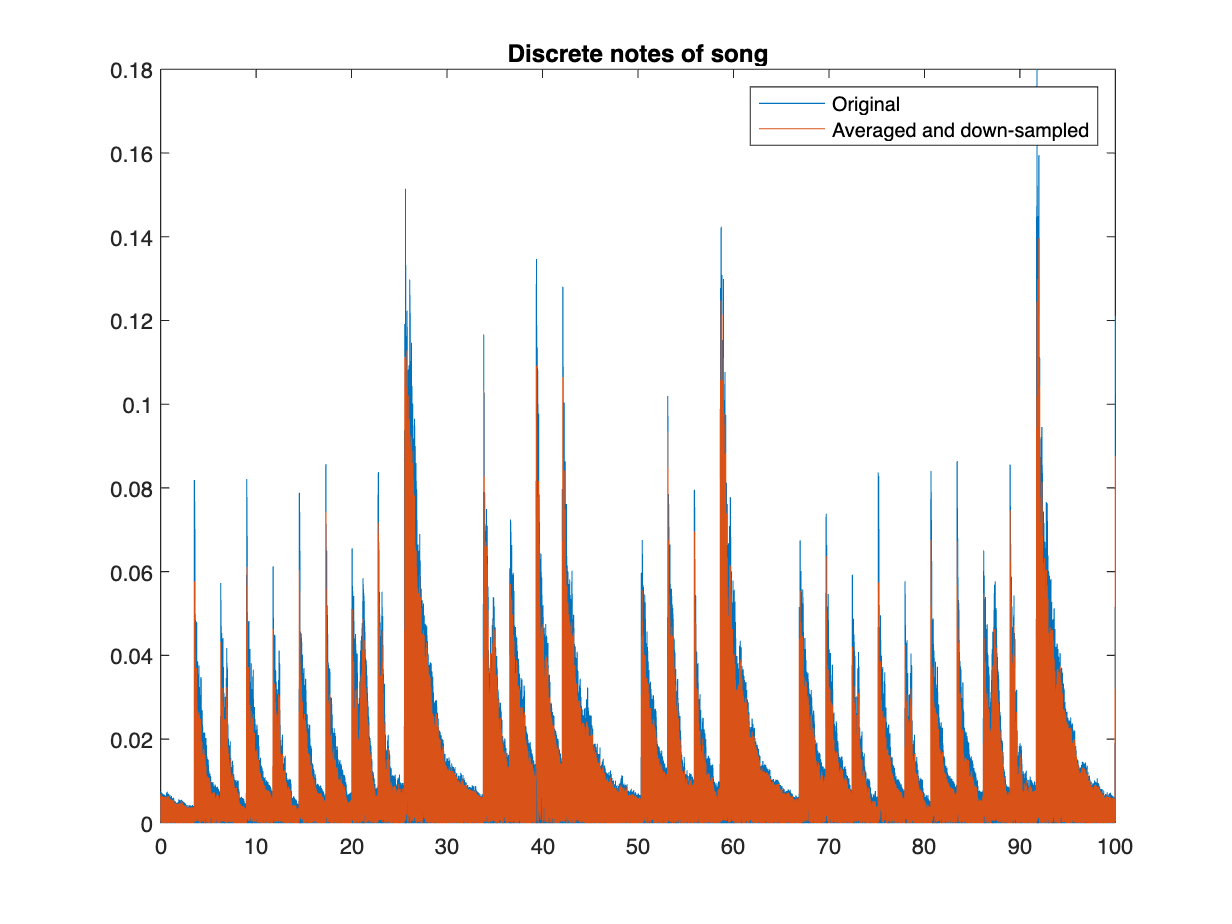

m = 20;
Fsm = round(Fs/m);
p = floor(n/m);
y_avg = zeros(1,p);
for i = 1:p
    y_avg(i) = mean(y(m*(i-1)+1:m*i));
end
figure, plot(linspace(0,100,n),abs(y)), hold on
plot(linspace(0,100,p),abs(y_avg))
title('Discrete notes of song')
legend('Original', 'Averaged and down-sampled')

if ~mute, sound(y_avg,Fsm); end

Adaptive (moving average) threshold to find notes The filter parameters depend on the song chosen

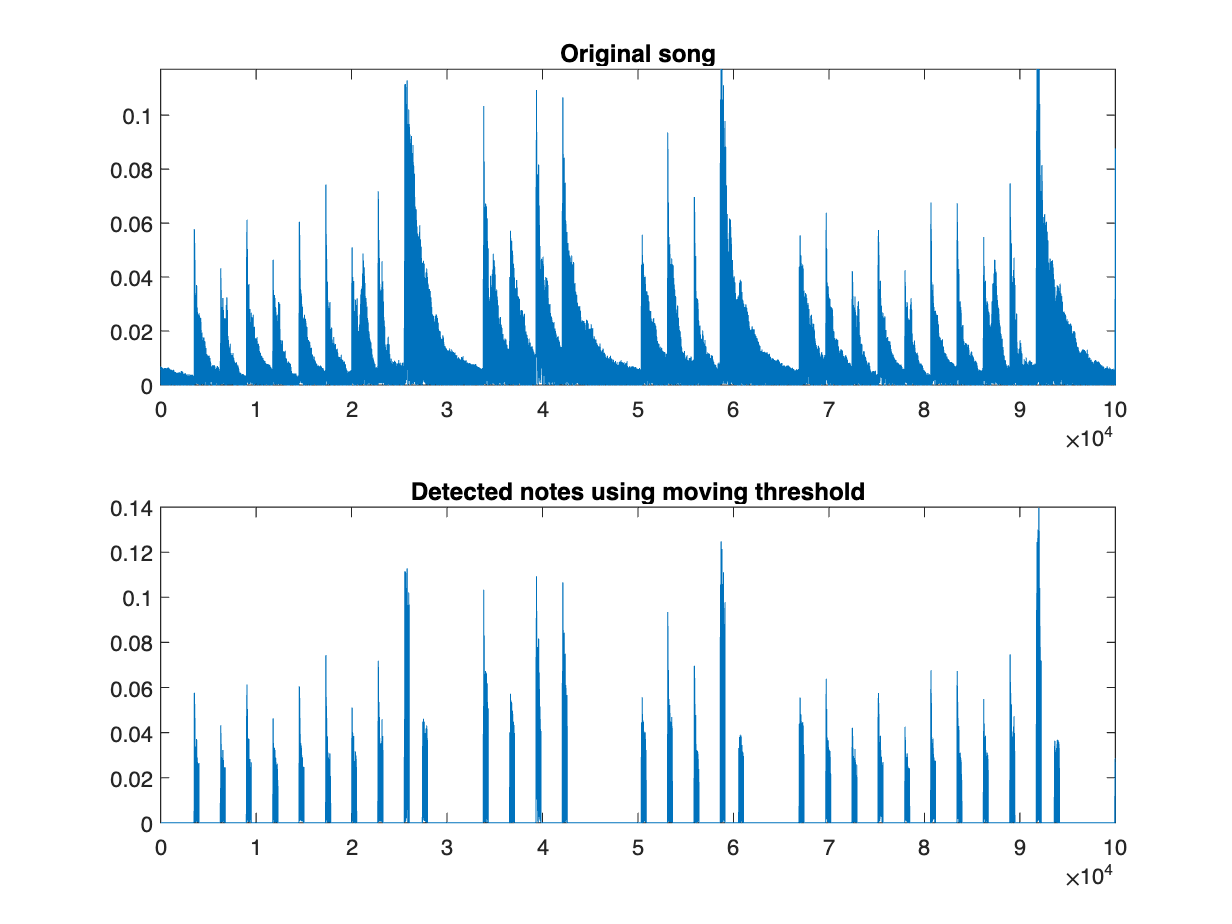

close all
y_thresh = zeros(1,p);
i = 1;
while (i <= p)
    thresh = 5*median(abs(y_avg(max(1,i-5000):i)));
    if (abs(y_avg(i)) > thresh)
        for j = 0:500
            if (i + j <= p)
                y_thresh(i) = y_avg(i);
                i = i + 1;
            end
        end
        i = i + 1400;
    end
    i = i + 1;
end

figure, subplot(2,1,1), plot(abs(y_avg)), title('Original song'), ylim([0 1.1*max(y_avg)])
subplot(2,1,2), plot(abs(y_thresh)), title('Detected notes using moving threshold')

if ~mute, sound(y_thresh,round(Fsm)); end

find frequencies of each note

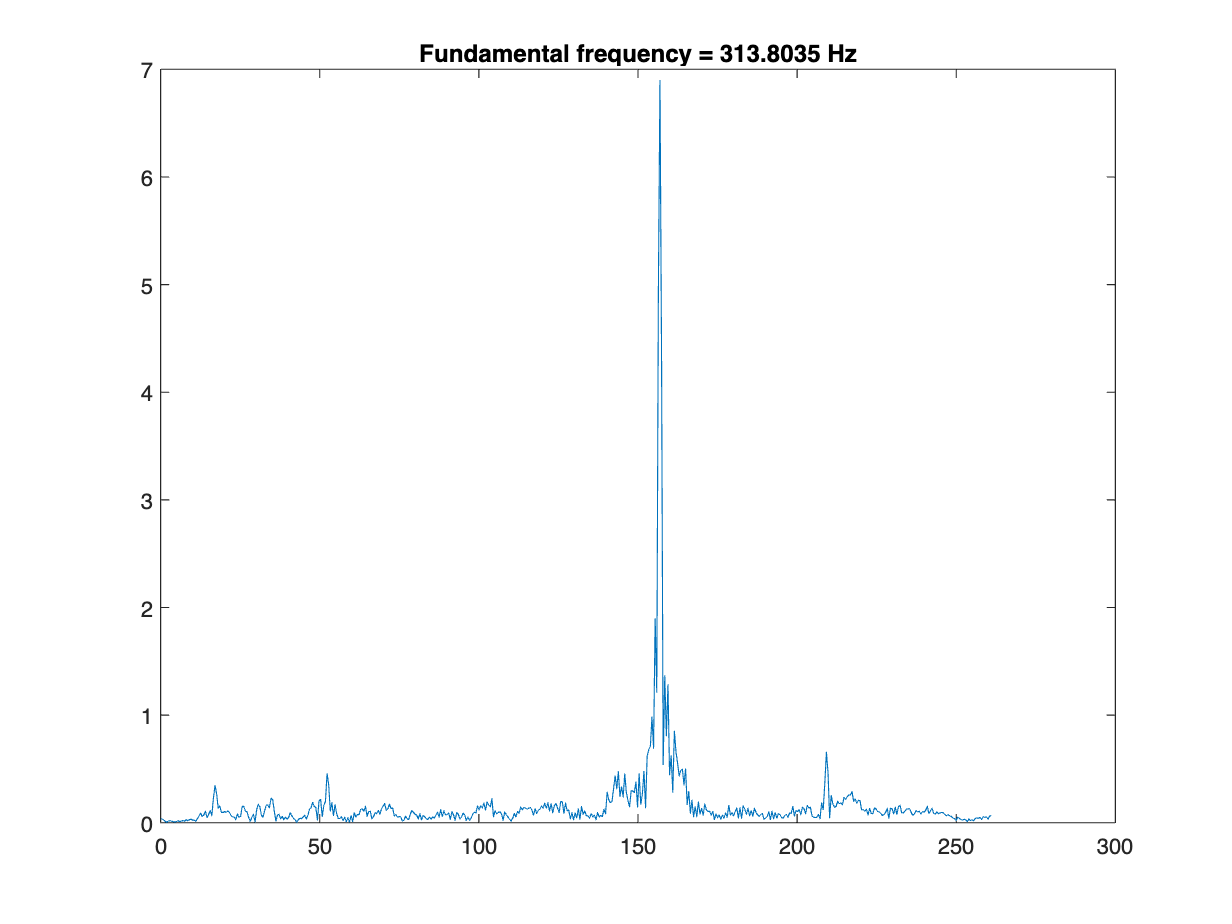

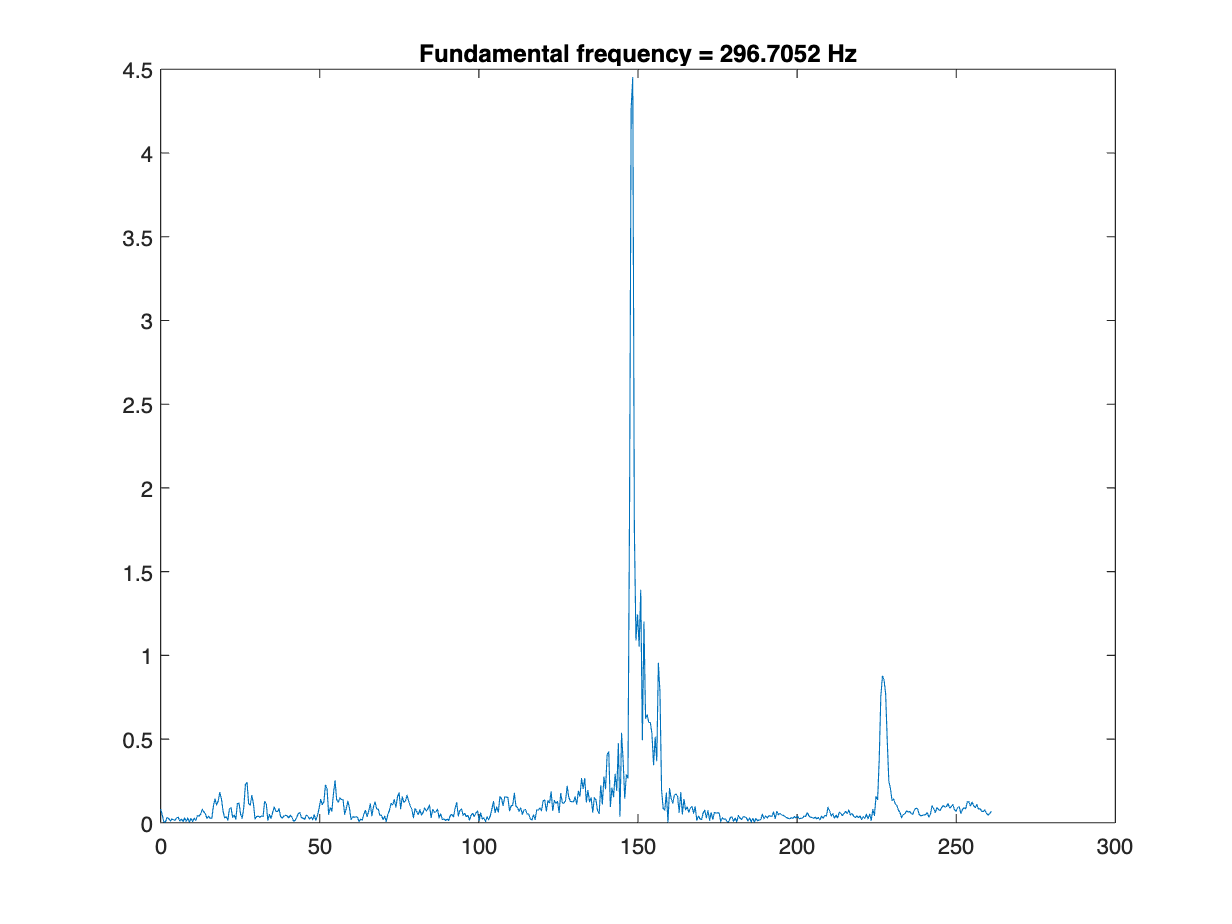

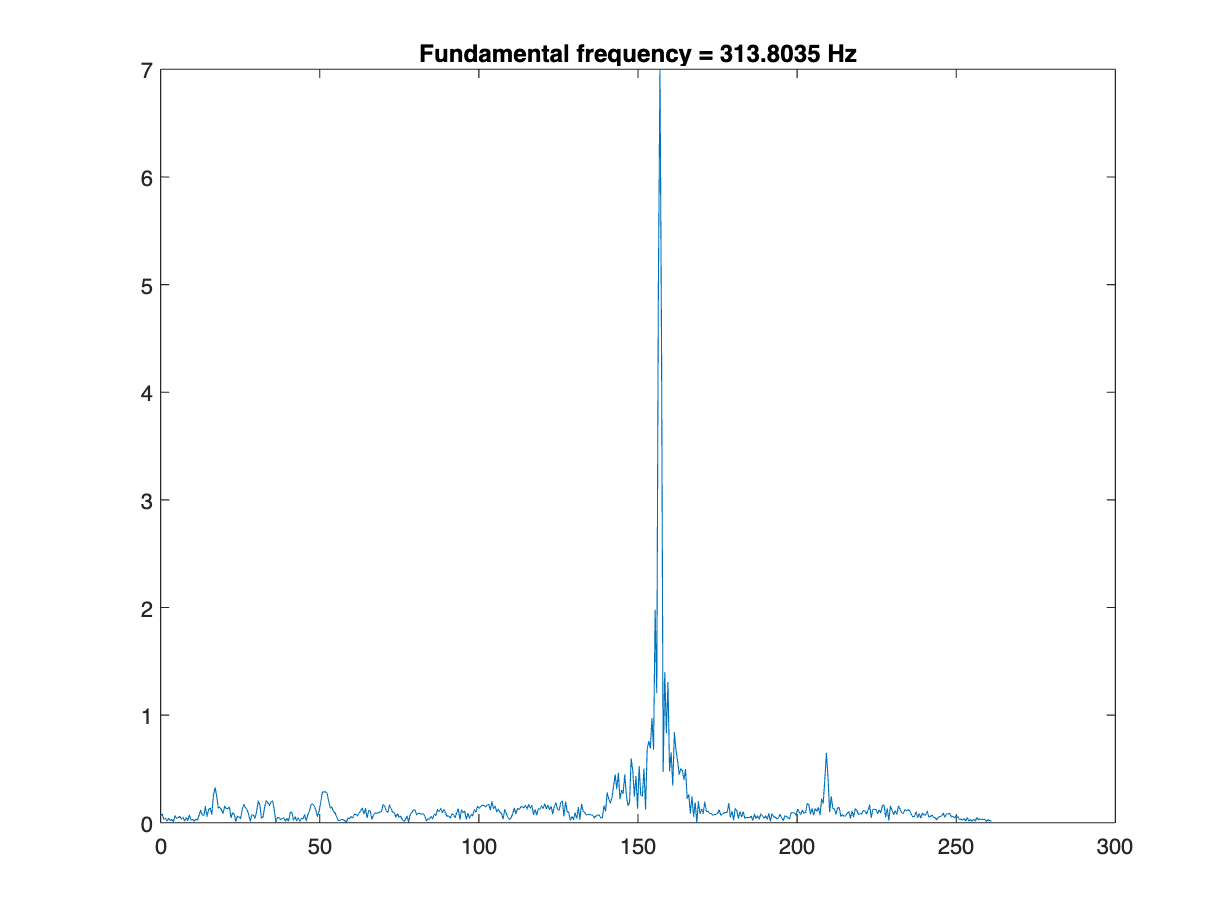

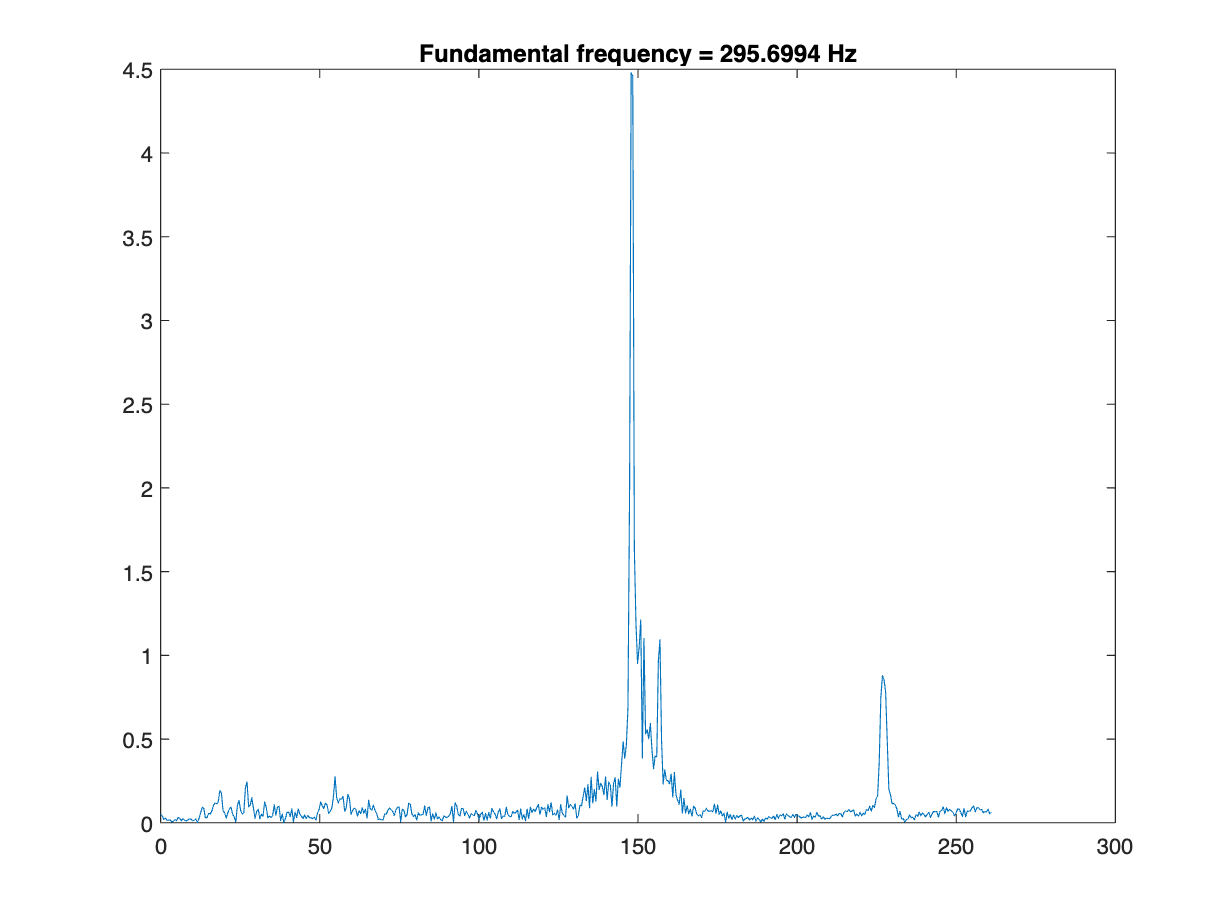

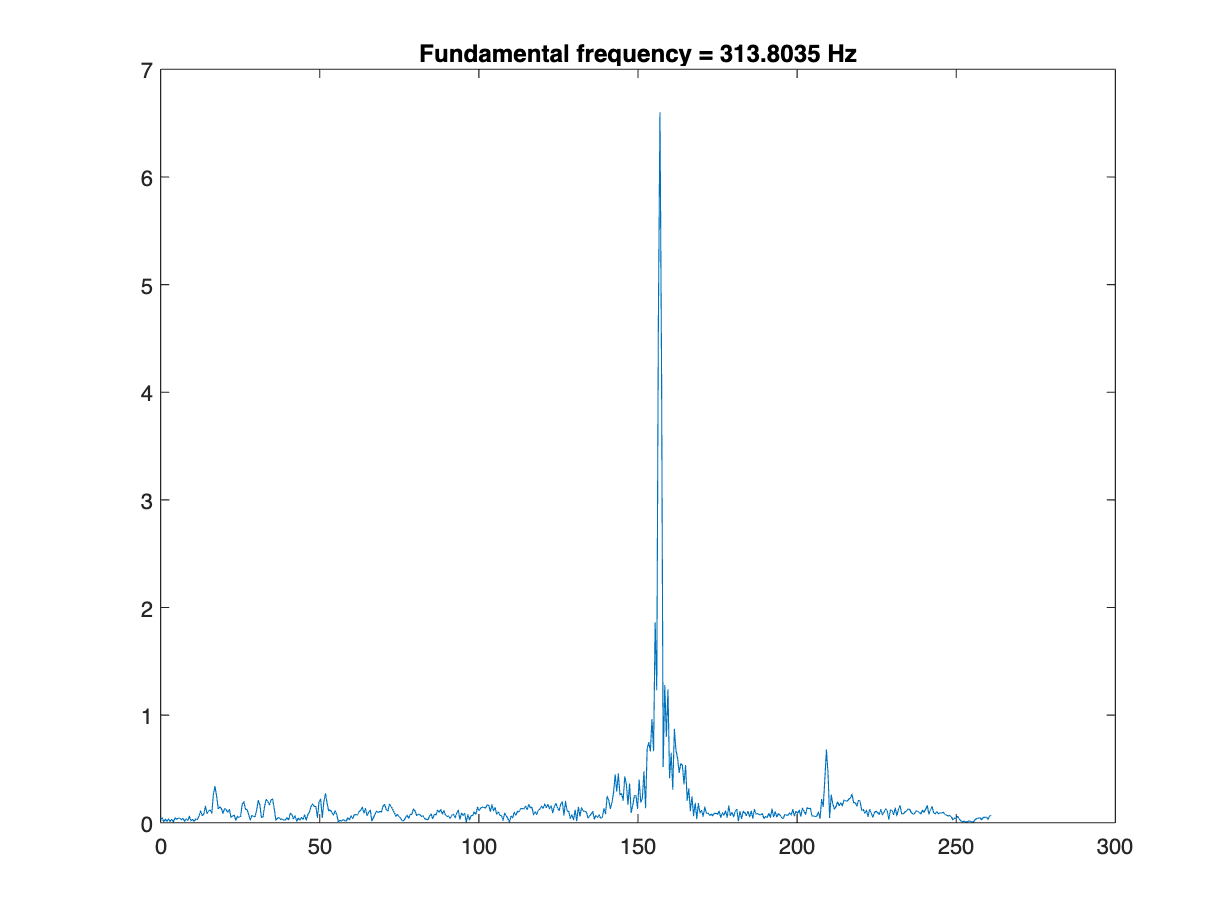

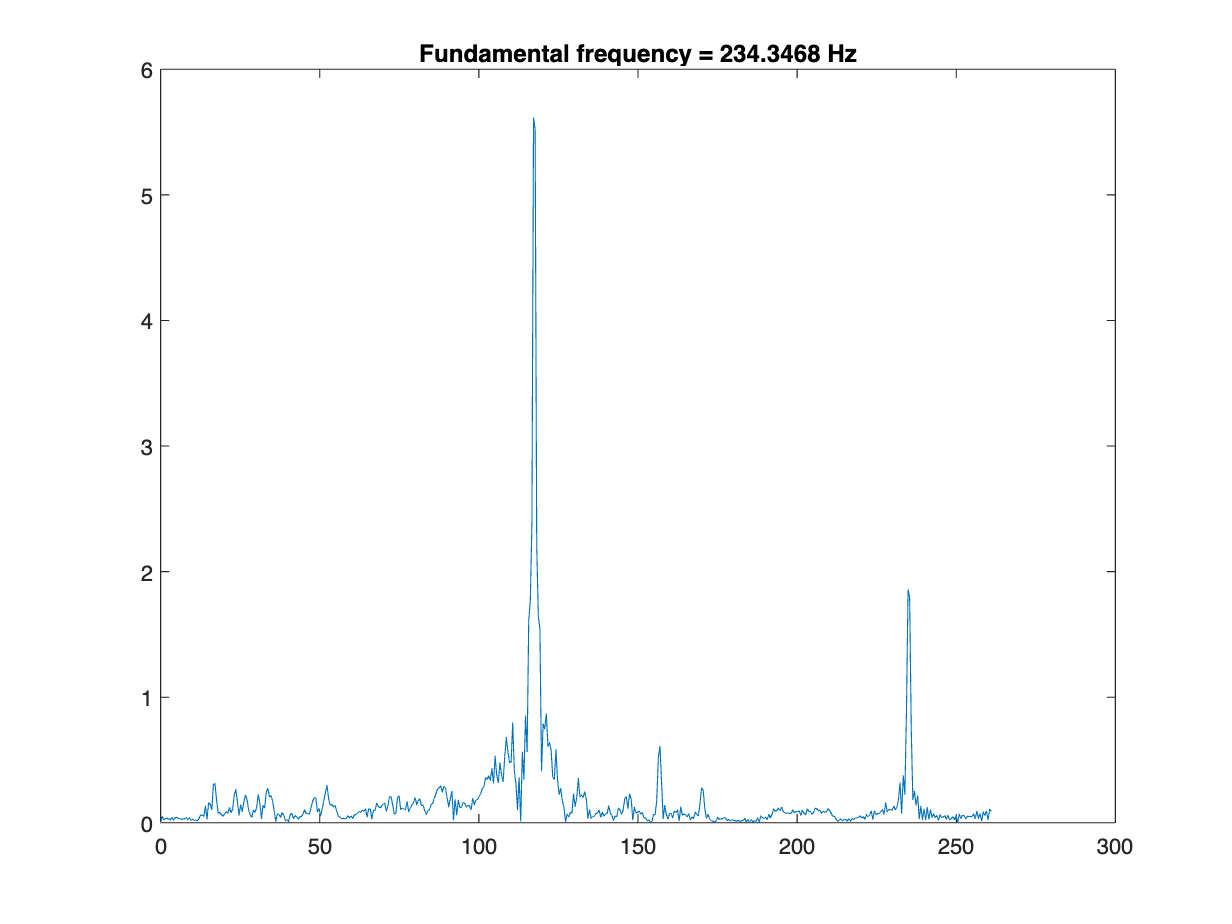

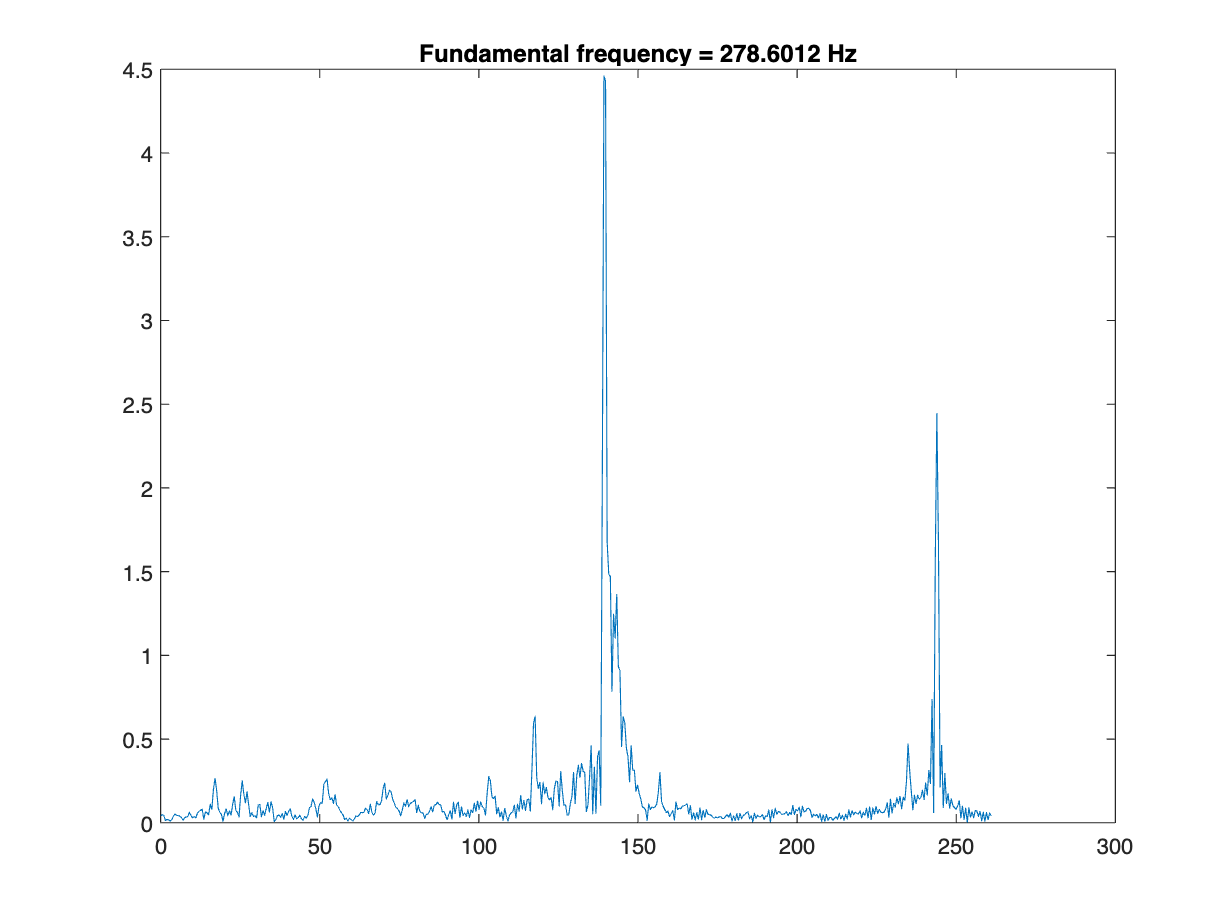

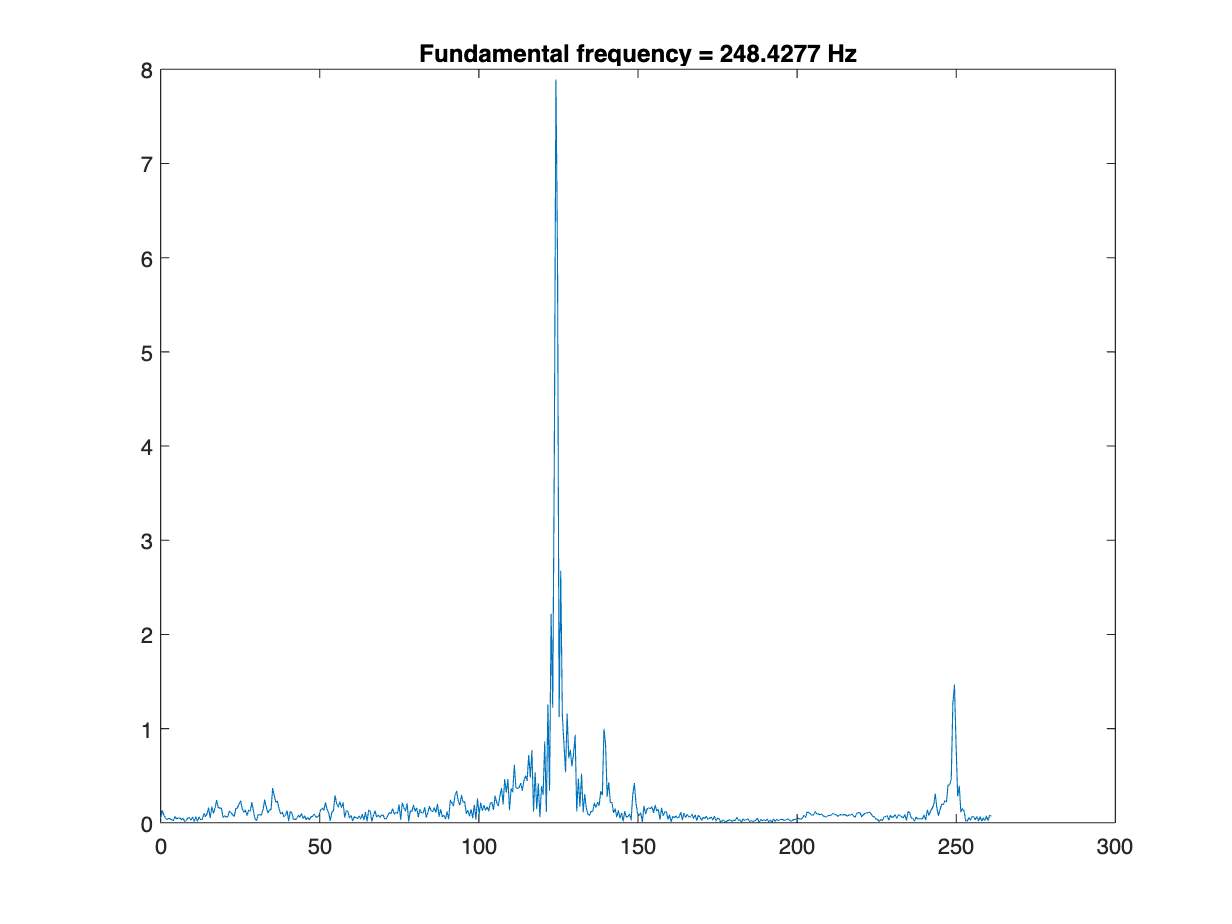

clc; close all

i = 1;
i_note = 0;
while i < p
    j = 1;
    end_note = 0;
    while (((y_thresh(i) ~= 0) || (end_note > 0)) && (i < p))
        note(j) = y_thresh(i);
        i = i + 1;
        j = j + 1;
        if (y_thresh(i) ~= 0)
            end_note = 20;
        else
            end_note = end_note - 1;
        end
        if (end_note == 0)
            if (j > 25)
                % pad note with zeros to double the size (N --> 2*N-1)
                note_padded = [note zeros(1,j)];
                Note = fft(note_padded);
                Ns = length(note);
                f = linspace(0,(1+Ns/2),Ns);
                [~,index] = max(abs(Note(1:length(f))));
                if (f(index) > 20)
                    i_note = i_note + 1;
                    fundamentals(i_note) = f(index)*2;
                    figure, plot(f,abs(Note(1:length(f))))
                    title(['Fundamental frequency = ',num2str(fundamentals(i_note)),' Hz'])
                    %plot(note_padded)
                end
                i = i + 50;
            end
            clear note;
            break
        end
        
    end
    i = i + 1;
end

## Part III . Results

% amplitude
amp = 0.1;
% sampling frequency
fs = 20500;
% duration
duration = .5;

% song recreation and note extraction
recreate_song = zeros(1,duration*fs*length(fundamentals));
for i = 1:length(fundamentals)
    [letter(i,1),freq(i)]= FreqToNote(fundamentals(i));
    values = 0:1/fs:duration;
    a = amp*sin(2*pi*freq(i)*values*2);
    recreate_song((i-1)*fs*duration+1:i*fs*duration+1) = a;
    if ~mute, sound(a,fs); pause(.5); end
end

% txt file with the notes
fileID = fopen('extracted_notes.txt','w');
fprintf(fileID,'%s',letter);
fclose(fileID);

% recreated song
audiowrite('song_recreated.wav',recreate_song,fs);
letter

letter = 30×1 string array
    "Eb4 "
    "D4 "
    "Eb4 "
    "D4 "
    "Eb4 "
    "Bb3 "
    "Db4 "
    "B3 "
    "Ab3 "
    "Ab2 "
    "B2 "
    "Eb3 "
    "Ab3 "
    "Bb3 "
    "Eb3 "
    "G3 "
    "Bb3 "
    "B3 "
    "Ab2 "
    "Eb3 "
    "Eb4 "
    "D4 "
    "Eb4 "
    "D4 "
    "Eb4 "
    "Bb3 "
    "Db4 "
    "B3 "
    "Ab3 "
    "Ab2 "


## References

[1] it.mathworks.com/matlabcentral/answers/547824-matlab-code-for-musical-note-recognition-based-on-frequency 

[2] Course Slides of Part I